## Entropy Based Voice Detection: Dynamic Threshold

### Read in Sound Data:

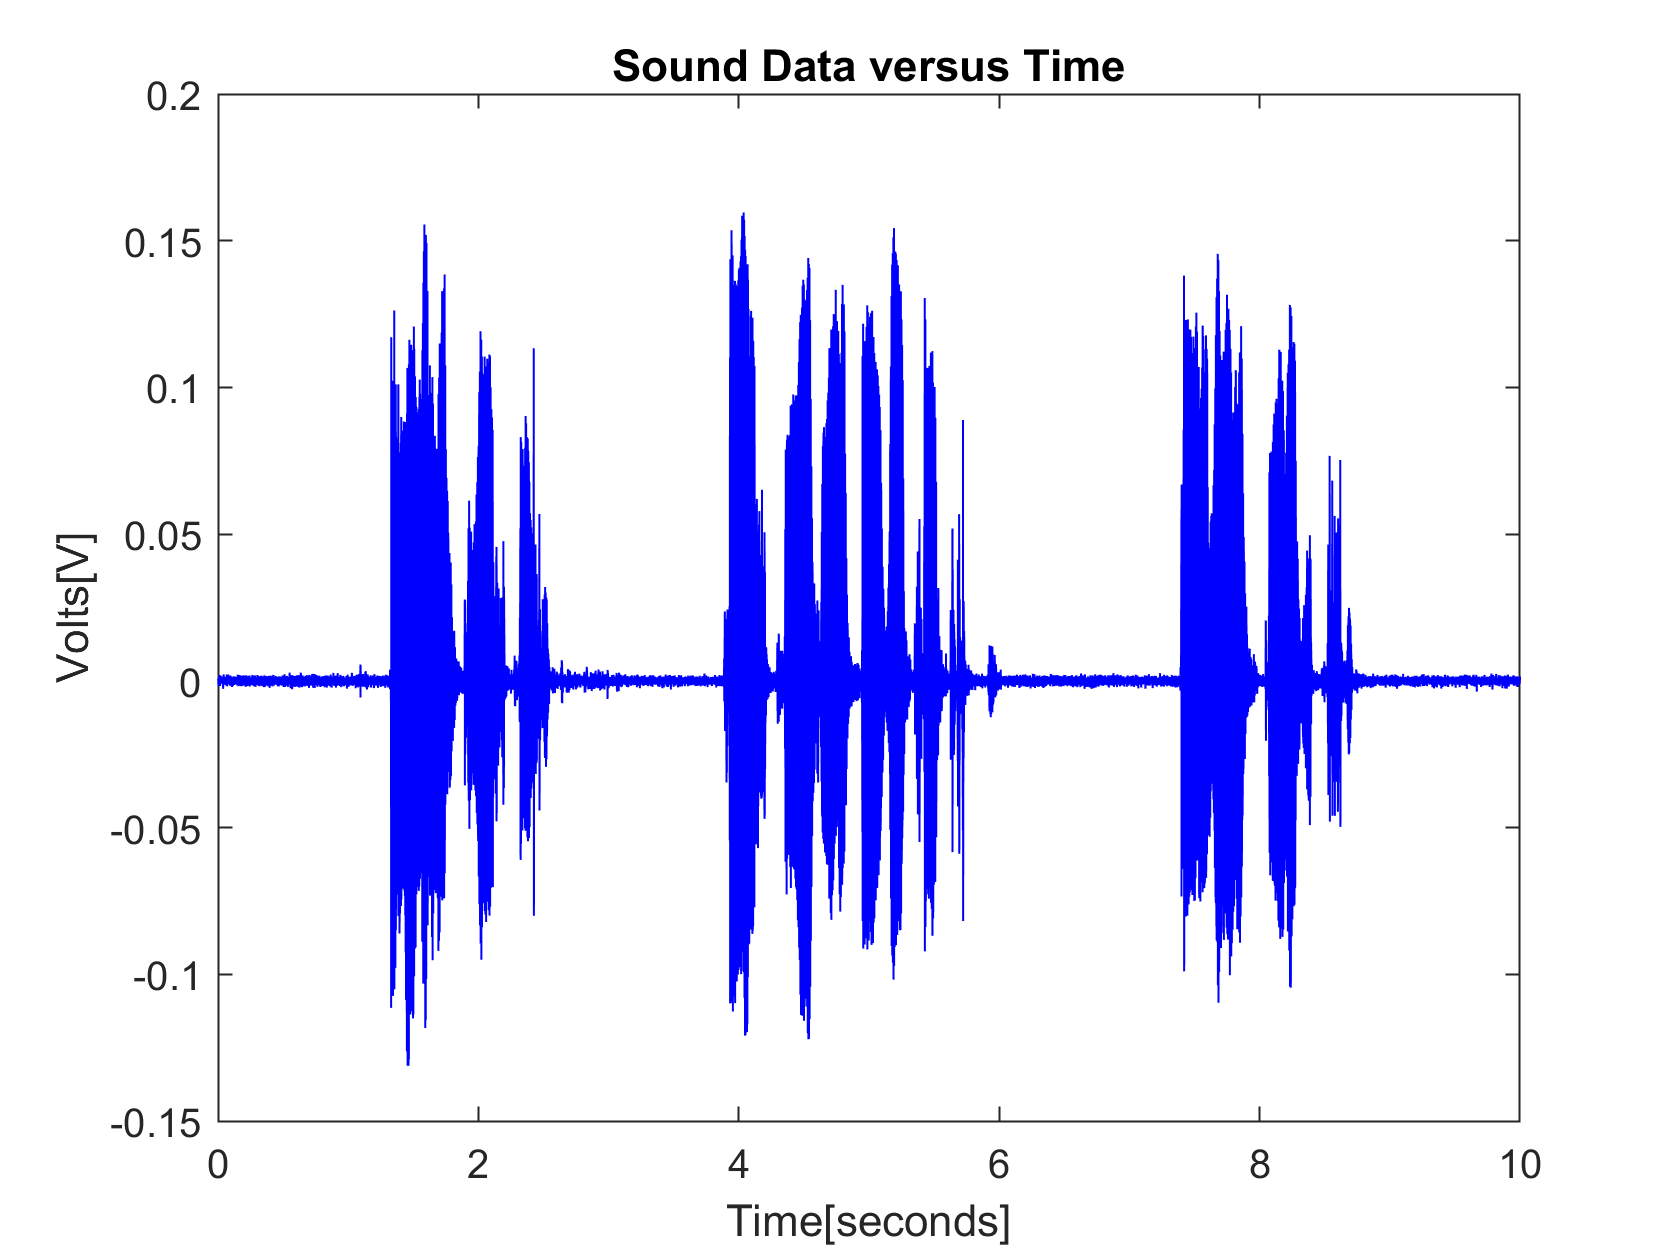

clear;
[d,s]= audioread('C:\DSP Project\clean_ness_speech.wav');
t = 0:1:length(d)-1;
t=t/s;
fs =s;
% 
for i =1:1:length(t)-1
    if t(i)==10
        c =i;
    end
end 
figure()
d = d(1:c);
t = t(1:c);
% % %for babble noise signals
% [d1, s1] = audioread('C:\DSP Project\babble.wav');
% d1 = interp(d1, 6);
% d1 = 0.1*d1;
% l=length(d1);
% d1(l+1)=0;
% n=d1+d';
% d=n;


% %for car noise signals
[d1, s1] = audioread('C:\DSP Project\car.wav');
d1 = interp(d1, 6);
d1 = 0.1*d1;
l=length(d1);
d1(l+1)=0;
n=d1+d';
d=n;

plot(t,d, 'b')
title('Sound Data versus Time')
xlabel('Time[seconds]');
ylabel('Volts[V]');

### Organise The Sound Data into Frames:

frame_length = 0.01;
n_frames = 10/frame_length;
sample_per_frame =frame_length*s;
last_samp = 1;
for k=1:1:n_frames
   new_d(:,k)= d(last_samp:last_samp+sample_per_frame) ;
   last_samp = last_samp + sample_per_frame;
end
new_d(sample_per_frame+1,:)=[];
new_d(:,1)=[]; %where every column is 1 frame (10ms long)
%check if first column is all 0

### Get the Entropy of Each Frame:

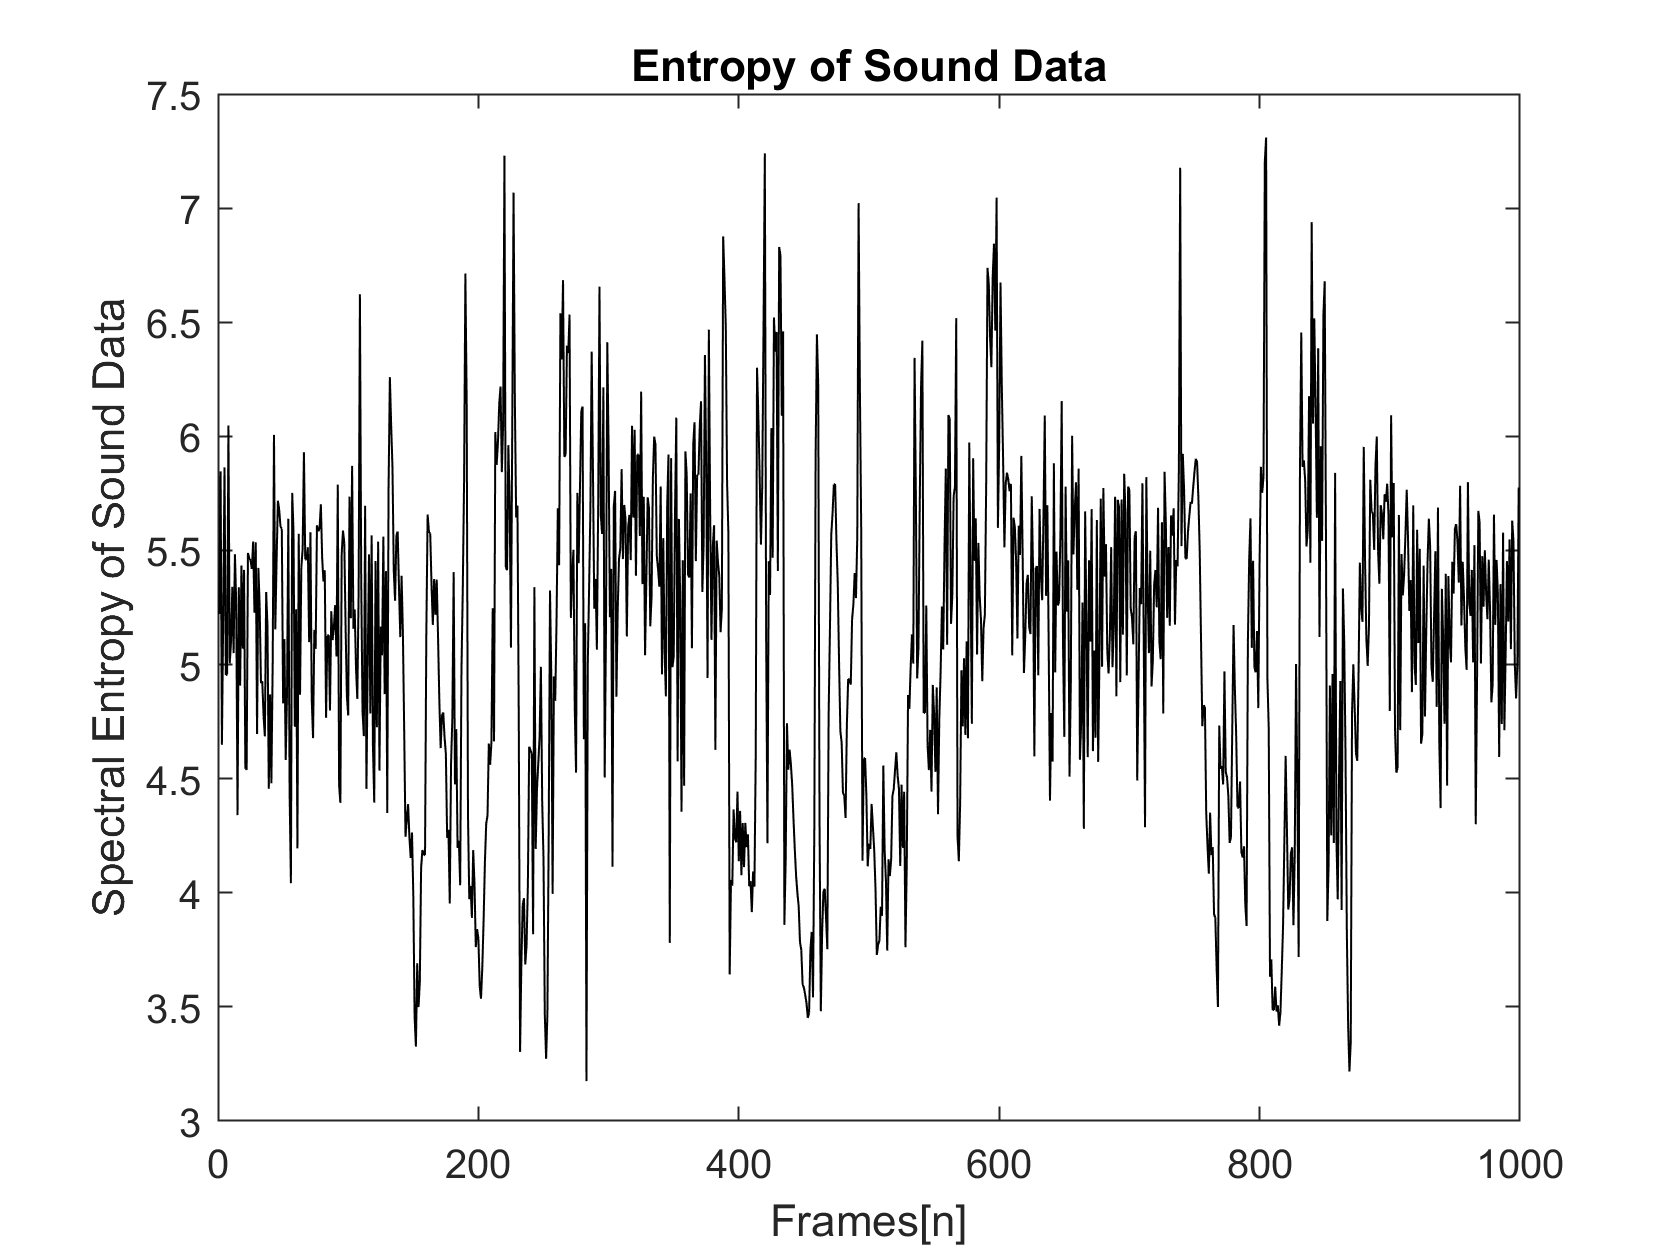

%Get FFT of each frame
NFFT=2^11;                      %NFFT-point DFT (s to next power of 2) 
for i = 1:1:999                 %Calculate FFT of each frame and Energy of each frequency
    x = new_d(:,i);
    X=fftshift(fft(x,NFFT));
    fVals=fs*(-NFFT/2:NFFT/2-1)/NFFT;
    X = X((NFFT/2)+1:end);
    fVals = fVals((NFFT/2)+1:end);
    E(:,i) = abs(X.*conj(X));
%     figure()
%     plot(fVals((NFFT/2)+1:end),abs(X((NFFT/2)+1:end)),'b');
%     title('Double Sided FFT - with FFTShift');
%     xlabel('Frequency (Hz)')
%     ylabel('|DFT Values|');
end
%E is energy of each frequency in each frame

% to find probability for every frequency in each frame
for i = 1:1:999
sum_E = sum(abs(E(:,i)));
pi = abs(E(:,i))./sum_E;
term = pi.*log2(pi);         %Normalise Probability function  
H(i) = -sum(term);            %Entropy of each frame
end
%H = movmean(H,15);            %Moving Average
figure()
plot(H,'k')                       %plot the Entropy 
title('Entropy of Sound Data');
xlabel('Frames[n]');
ylabel('Spectral Entropy of Sound Data');

### Normal Distribution of Entropy (Demonstration):

% H30 = H(1:30);
% NH30 = H(31:60);
% pd = fitdist(H30','normal');
% pd1=fitdist(NH30','normal');
% x = 6.5:0.01:7.5;
% y =pdf(pd,x);
% y1 = pdf(pd1,x);
% %Find the intersect of the two normal distributions
% m1 = pd.mu;
% std1 = pd.sigma;
% m2 = pd1.mu;
% std2 = pd1.sigma;
% a = 1/(2*std1^2) - 1/(2*std2^2);
% b = m2/(std2^2) - m1/(std1^2);
% c = m1^2 /(2*std1^2) - m2^2 / (2*std2^2) - log(std2/std1);
% intersect = min(roots([a,b,c]))
% %plot
% figure()
% plot(x,y,'b')
% hold on
% plot(x,y1)
% title("Normal Distribution of Spectral Entropy of two sets of 30 frames");
% xlabel("Spectral Entropy");
% ylabel("Probability Desnity");

### Classify Frames:

noise = H(1:27);                %First 27 frames classified as noise automatically
VAD(1:27) = 0;                  
l = 27;
speech_count =0;
for i=1:1:36                    %classify thresholds in batches of 27 frames
  n27 = H((27*i)+1:(27*(i+1))); 
  %get the normal distibrutions of the current and previous 27 frames
  pd_noise = fitdist(noise','normal');
  pd_n27 = fitdist(n27','normal');
  x = 0:0.01:5; %might change per clip
  y_noise =pdf(pd_noise,x);
  y_n27 = pdf(pd_n27,x);
  %find the intersect of the distributions 
  m1 = pd_noise.mu;
  std1 = pd_noise.sigma;
  m2 = pd_n27.mu;
  std2 = pd_n27.sigma;
  a = 1/(2*std1^2) - 1/(2*std2^2);
  b = m2/(std2^2) - m1/(std1^2);
  c = m1^2 /(2*std1^2) - m2^2 / (2*std2^2) - log(std2/std1);
  threshold = min(roots([a,b,c]));  %Threshold = intersection of distributions
  
  for j = 1:1:27                    %for each frame in the batch
      if n27(j)<threshold           %if entropy of frame less than threshold
          VAD(l+1) = 1;             %Speech Detected
      else
          VAD(l+1)=0;               %Noise Detected
          l_noise = length(noise);
          noise(l_noise +1)=n27(j);
      end
      l = l+1;
  end
l = length(VAD); 

  end
VAD = movmean(VAD,30);  
VAD = movmean(VAD, 30);
VAD = smooth(VAD);
%moving average filter

### Plot the Energy and Voice Detection:

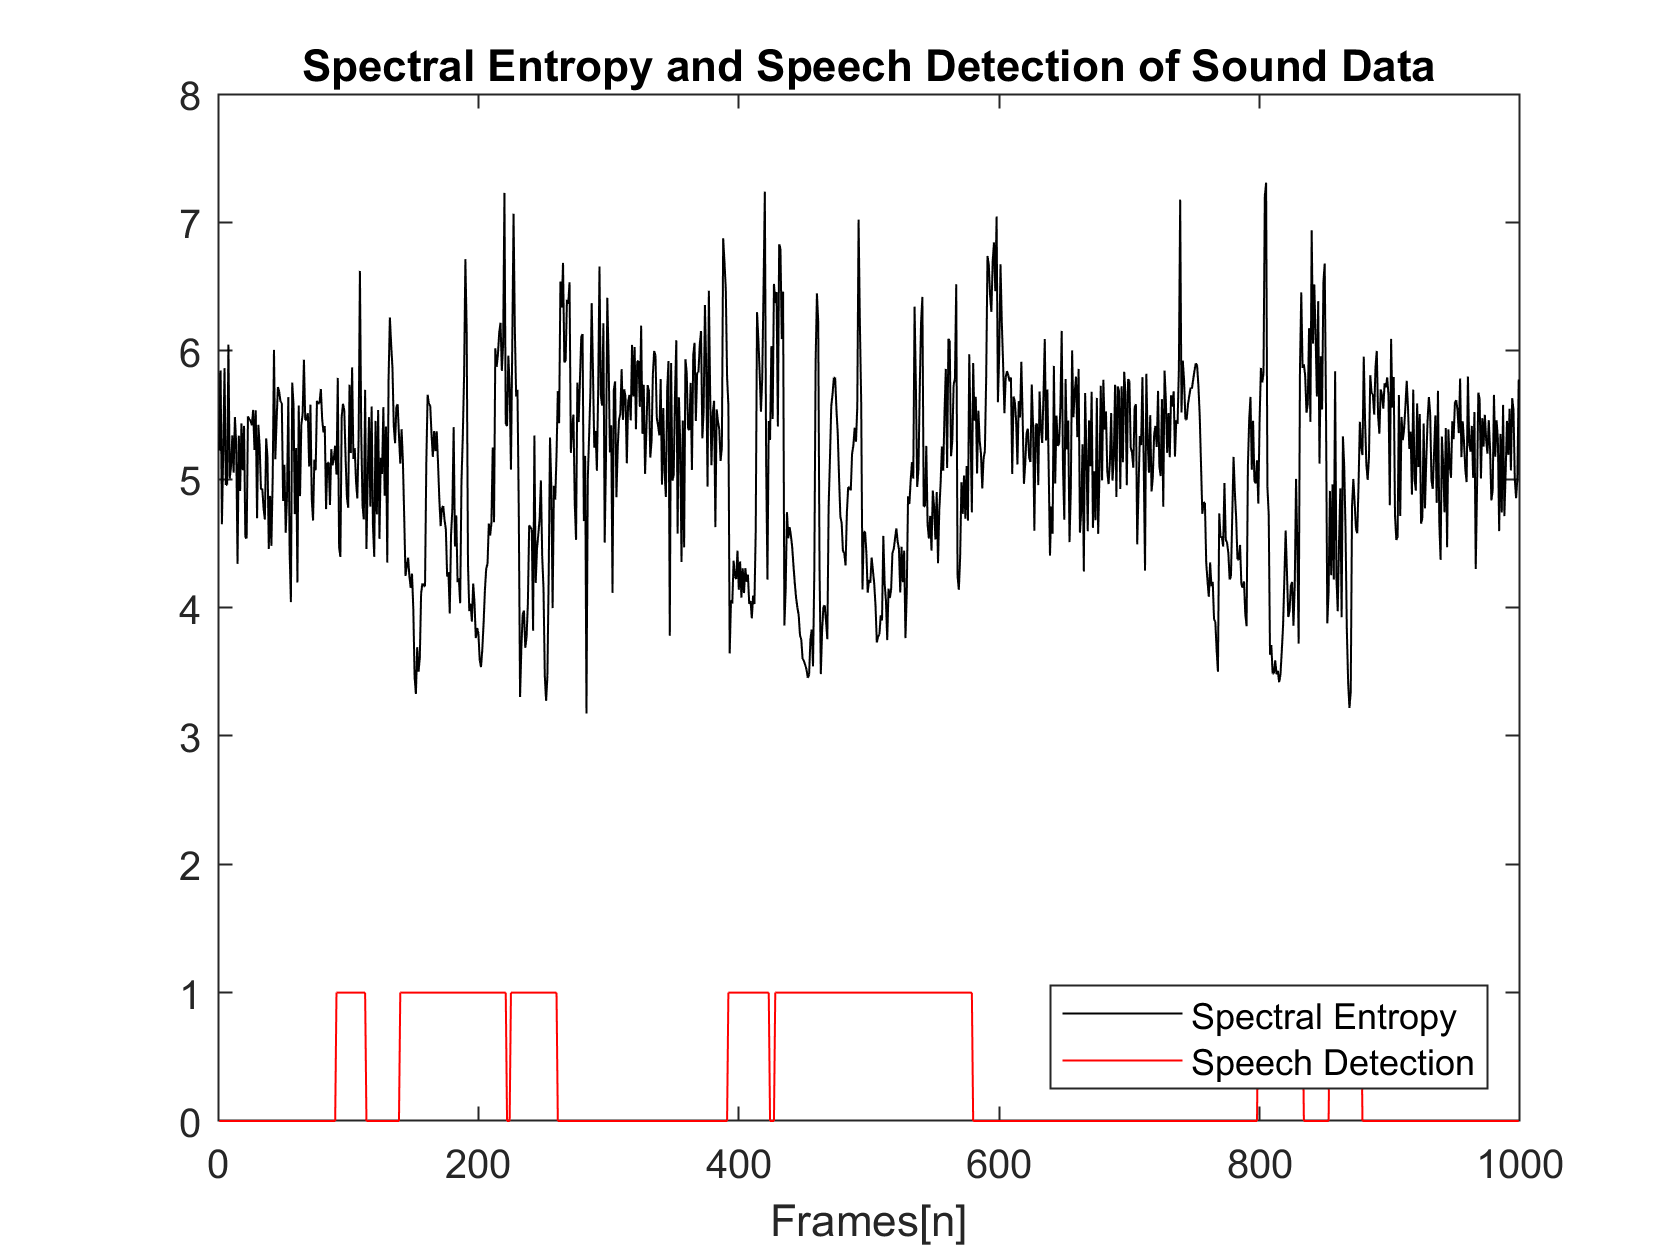

for i = 1:1:length(VAD)
    if VAD(i)<0.4578
        VAD(i)=0;
    else VAD(i) = 1;
    end
end

% num = 1;
% for i=1:1:length(VAD)/27
%     check = VAD(num:i*27);
%     c = mode(check);
%     VAD_new(num:i*27) = c;
%     num = i*27+1;
% end

VAD_new = VAD;

figure()
plot(H,'k')
hold on
plot(VAD_new,'r')
title('Spectral Entropy and Speech Detection of Sound Data');
xlabel("Frames[n]");
legend("Spectral Entropy","Speech Detection","Location" ,"southeast");

### Plot the Sound Data and Voice Detection:

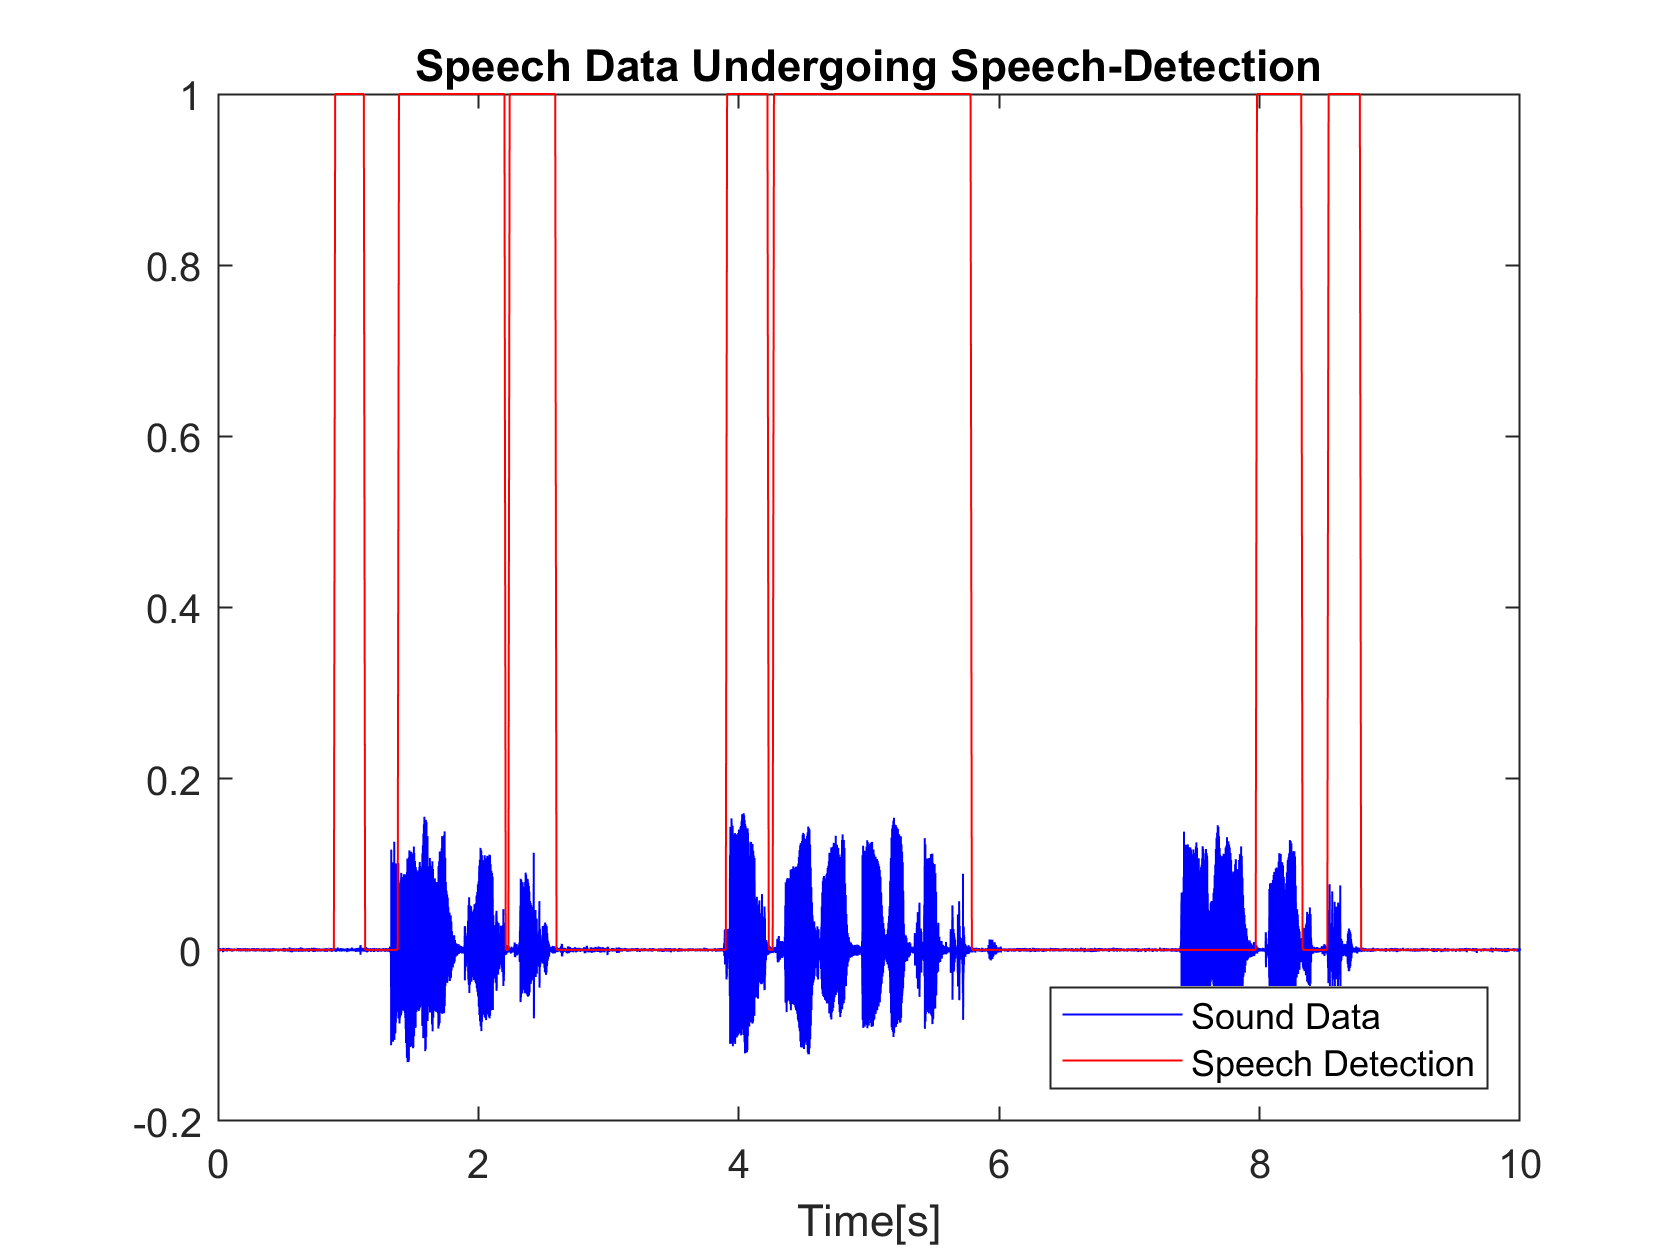

VAD_time(1)=0;
for i = 1:1:length(VAD_new)-1
    VAD_time(i+1)= 0.01*i;
end

figure()
plot(t,d, 'b');
hold on
plot(VAD_time,VAD_new, 'r')
title('Speech Data Undergoing Speech-Detection');
xlabel("Time[s]");

legend("Sound Data","Speech Detection","Location" ,"southeast");

## Find % accuracy

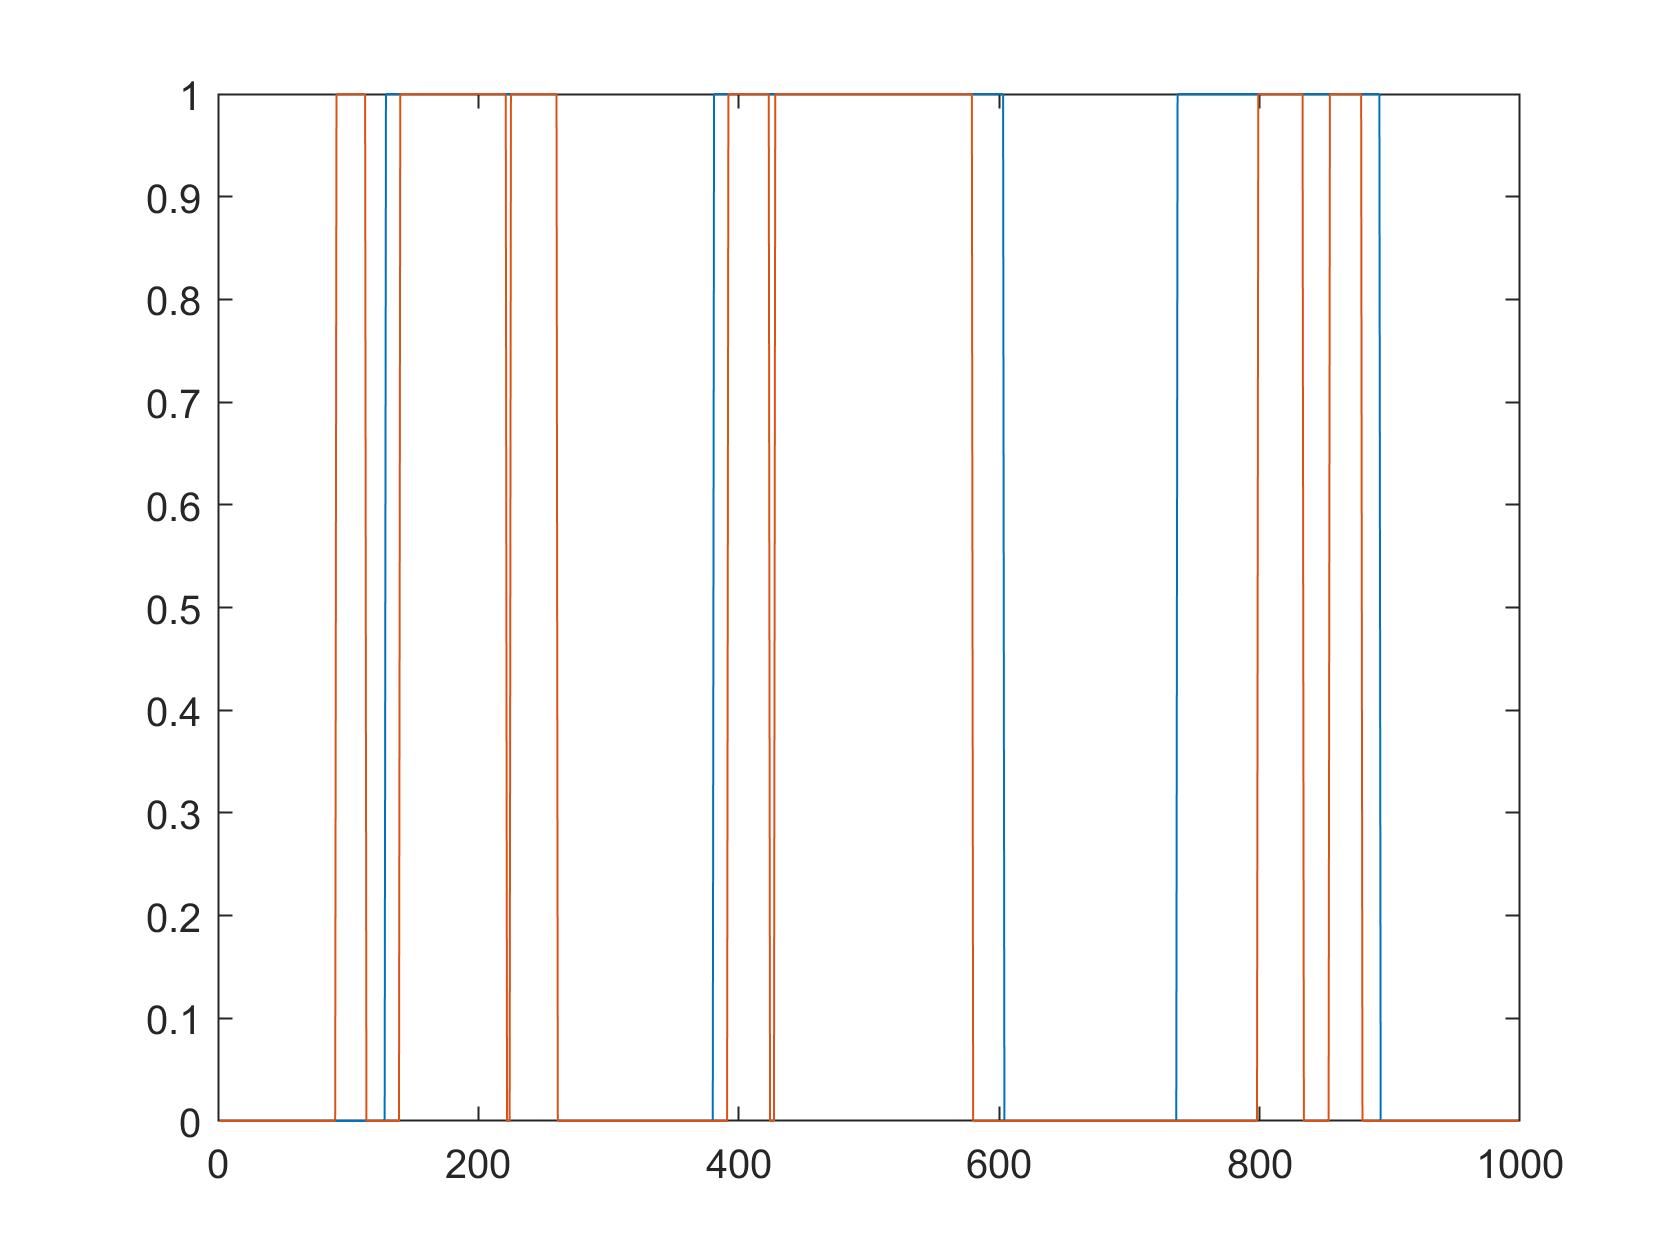


%for clean/white noise speech or babble noise
VAD_labelled(1:128) =0;
VAD_labelled(129:260)=1;
VAD_labelled(261:380) = 0;
VAD_labelled(381:603) = 1;
VAD_labelled(604:736) = 0;
VAD_labelled(737:893) = 1;
VAD_labelled(893:999) = 0;

%for office noise clip

% VAD_labelled2(1:181) = 0;
% VAD_labelled2(182:421) = 1;
% VAD_labelled2(422:476) = 0;
% VAD_labelled2(477:699) = 1;
% VAD_labelled2(700:709) = 0;
% VAD_labelled2(710:776) = 1;
% VAD_labelled2(777:825) = 0;
% VAD_labelled2(826:982) = 1;
% VAD_labelled2(983:999) = 0;

figure();
% plot(VAD_new); hold on; 
plot(VAD_labelled); hold on; plot(VAD_new);

num_correct=0;
for i=1:1:999
    if VAD_new(i)==VAD_labelled(i)
        num_correct=num_correct+1;
    end
end
num_correct

num_correct = 827

pc_correct = num_correct/999 * 100

pc_correct = 82.7828

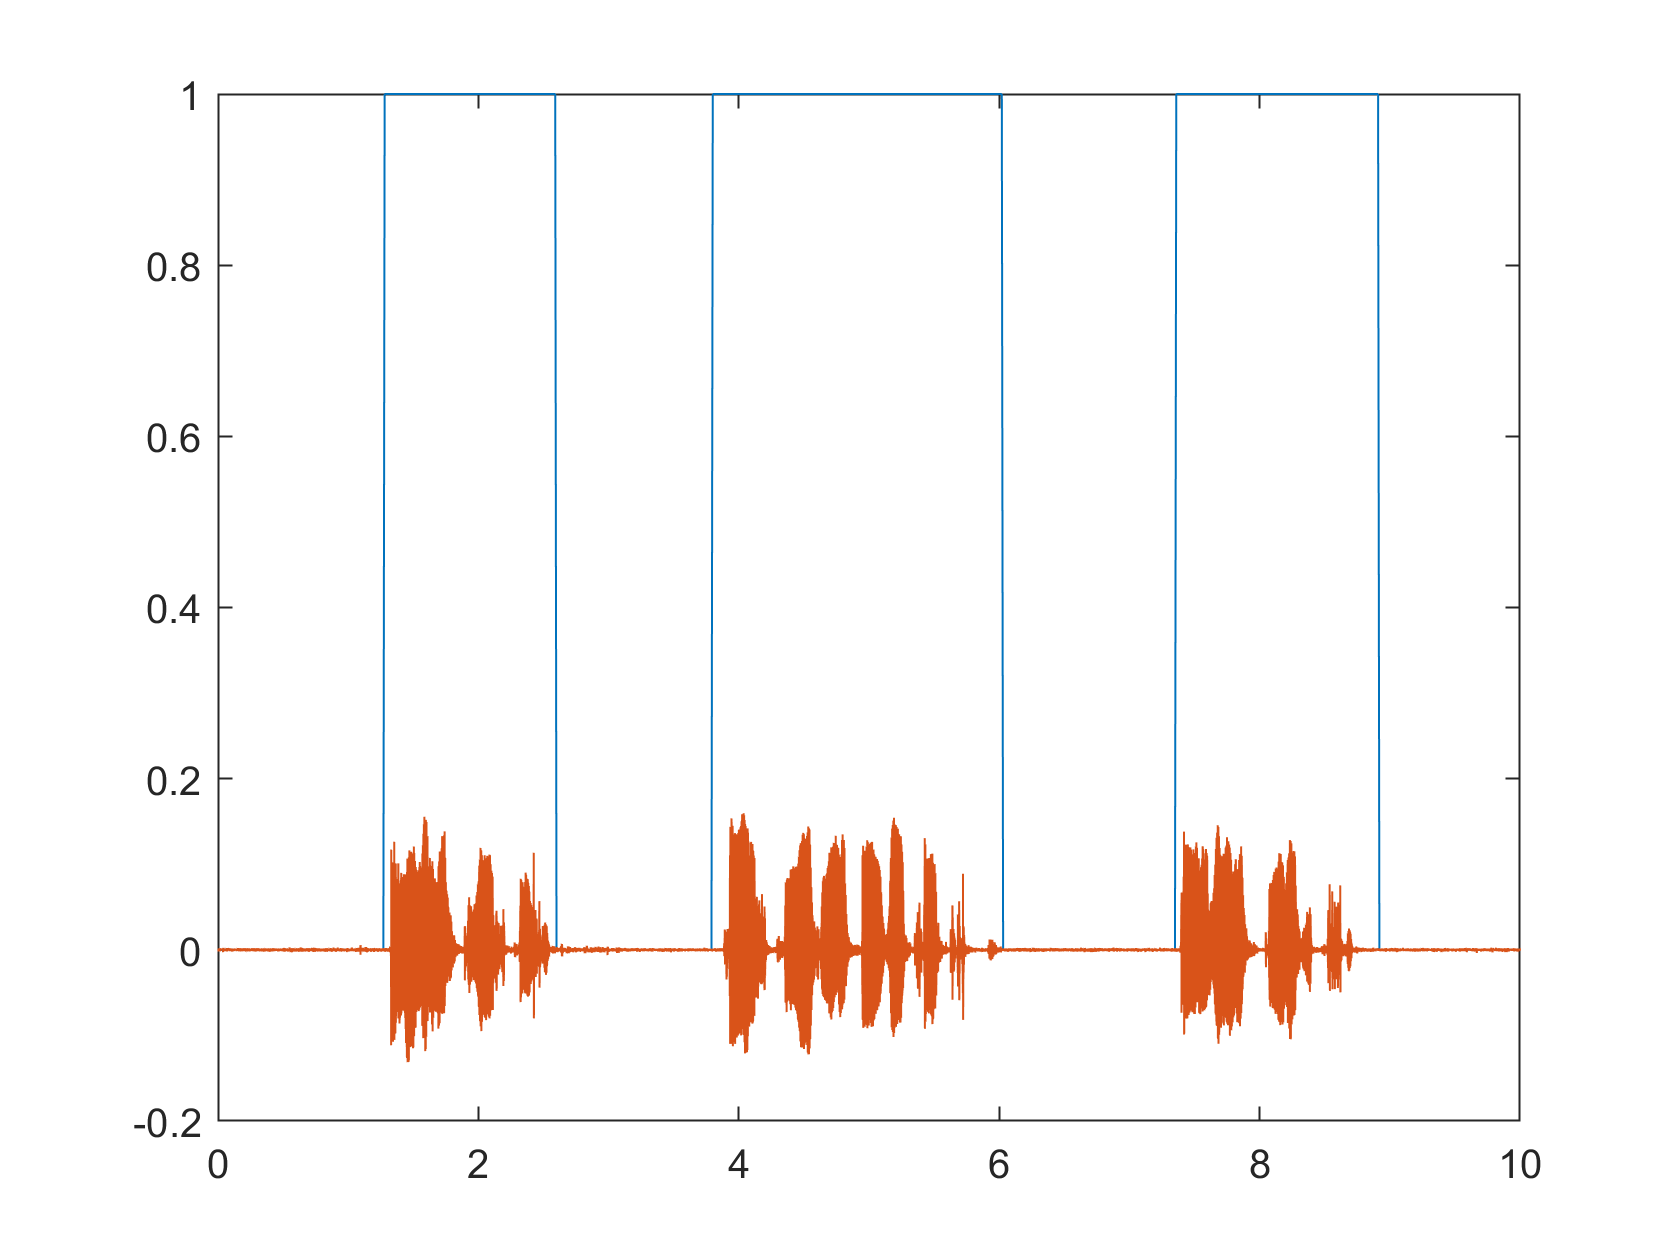

VAD_time(1)=0;
for i = 1:1:length(VAD_labelled)-1
    VAD_time(i+1)= 0.01*i;
end
figure(); plot(VAD_time, VAD_labelled); hold on; plot(t,d);